# Pràctica 7. Exercici 1

Exercici 6 del document CN_full4.pdf

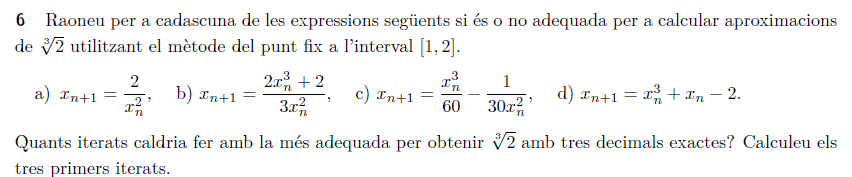

================================================================================

% Symbolic toolbox
syms t
valor = nthroot(2,3)    % arrel cúbica

valor =        1.2599


- `Verifiqueu si l'interval [1,2] conté la solució real de l'equació `$x^3 = 2$`.`

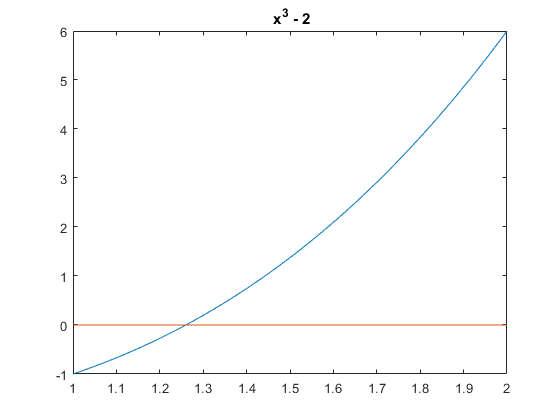

fplot([t^3-2,0],[1,2]), title(' x^3 - 2')

- `Estudieu la convergència del mètode `$x_{n+1}=\displaystyle\frac{2}{x_n^2}$` en l'interval [1,2].`

g1(t) = 2/t^2;
dg1(t) = diff(g1(t),t), vpa(dg1(1.26))  % sembla que no es convergent

$$dg1(t) = -\frac{4}{t^{3}}$$

$$ans = -1.9996240706747131539270617123981$$

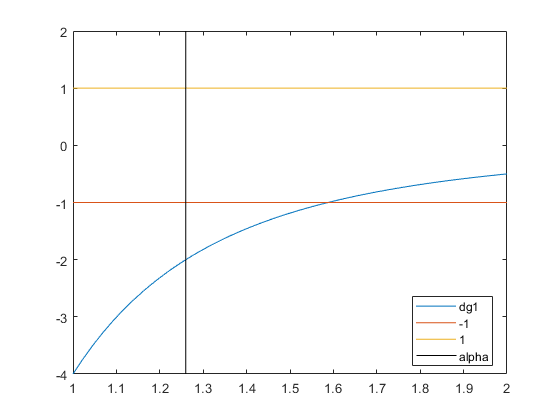

fplot([dg1,-1,1],[1,2])
hold on
line([valor,valor],[-4,2],'Color','k'),hold off
legend('dg1','-1','1','alpha','Location','best')

consistencia = double(g1(valor) - valor)

consistencia =   -7.7698e-17


- `Estudieu la convergència del mètode `$x_{n+1}=\displaystyle\frac{2x_n^3+2}{3x_n^2}$ `en l'interval [1,2].`

g2(t) = (2*t^3+2)/(3*t^2);
dg2(t) = diff(g2(t),t), vpa(dg2(1))  % convergent

$$dg2(t) = 2-\frac{2\,\left(2\,t^{3}+2\right)}{3\,t^{3}}$$

$$ans = -0.66666666666666666666666666666667$$

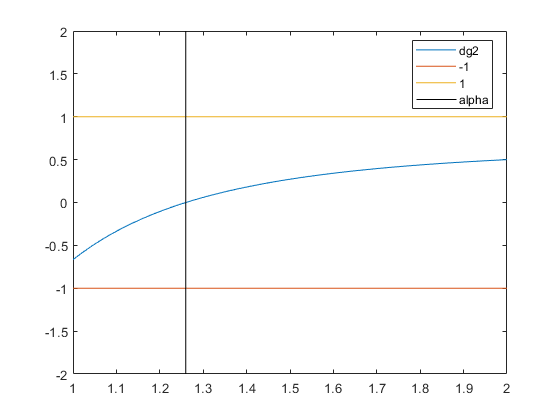

fplot([dg2,-1,1],[1,2])
hold on
line([valor,valor],[-2,2],'Color','k'),hold off
legend('dg2','-1','1','alpha','Location','best')

 consistencia = double(g2(valor) - valor)

consistencia =   -2.5899e-17


- `Estudieu la convergència del mètode `$x_{n+1}=\displaystyle\frac{x_n^3}{60}-\displaystyle\frac{1}{30x_n^2}$ `en l'interval [1,2].`

g3(t) = t^3/60 - 1/(30*t^2);
dg3(t) = diff(g3(t),t), vpa(dg3(1))  % metode convergent pero no a arrel cubica de 2

$$dg3(t) = \frac{t^{2}}{20}+\frac{1}{15\,t^{3}}$$

$$ans = 0.11666666666666666666666666666667$$

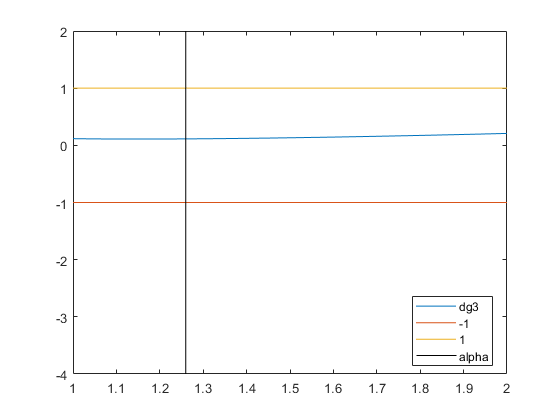

fplot([dg3,-1,1],[1,2])
hold on
line([valor,valor],[-4,2],'Color','k'),hold off
legend('dg3','-1','1','alpha','Location','best')

 consistencia = double(g3(valor) - valor)

consistencia =       -1.2476


- `Estudieu la convergència del mètode `$x_{n+1}=x_n^3+x_n-2$` en l'interval [1,2].`

g4(t) = t^3+t-2;
dg4(t) = diff(g4(t),t), double(dg4(1.2))    % no es convergent

$$dg4(t) = 3\,t^{2}+1$$

ans =          5.32


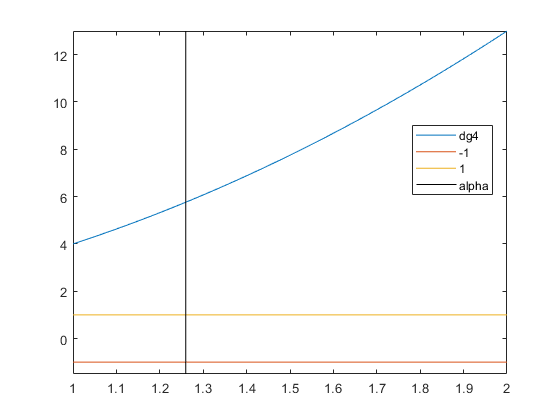

fplot([dg4,-1,1],[1,2]),hold on
line([valor,valor],[-1.5,13],'Color','k'),hold off
legend('dg4','-1','1','alpha','Location','best')

 consistencia = double(g4(valor) - valor)

consistencia =    1.2334e-16


- `Quin mètode és convergent? Quin és divergent? Comenta les diferències trobades.`

% L'unic mètode convergent a arrel cubica de 2, es la segona expressió.
% f(x) = 0 -> x = x - lambda(f(x)) |g(x,lambda)|<1

- `Quin mètode és el més adequat per obtenir `$\sqrt[3]{2}$?  `Quants iterats caldria fer amb la més adequada? Calculeu el tres primers iterats per aquest mètode. `

% La 2 que es de Newtown
x = 1;
if abs(dg2(x)) < 1  % teorema de convergència
    for n = 1:3
        x = g2(x)   % iterats
    end
end

$$x = \frac{4}{3}$$

$$x = \frac{91}{72}$$

$$x = \frac{1126819}{894348}$$

xsol = double(x)

xsol =        1.2599


er = abs(double(x-valor))

er =    1.2444e-05


decimals = fix(-log10(2*abs(valor-xsol)))   % Quatre decimals correctes

decimals =      4
